# Gain plot for JASA

close all
clear variables

testFo = 240;
fmCent = 20;
fl = 80;
fh = 400;
nOct = 48;
outDirName = "/Volumes/SSPL-UT/testCAPRICEP/";
output = fmTransfTestPeriodicRev(testFo, fmCent, @pitchOpenSmileS);

zsh:1: command not found: SMILExtract


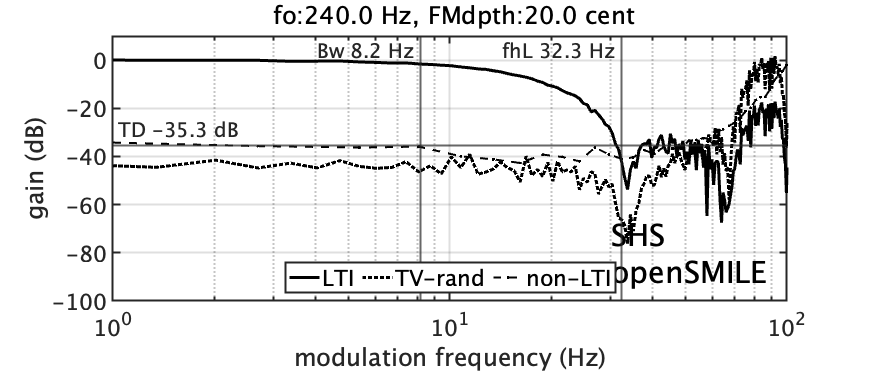

handle1 = figure;
%titleStr = output.testCondStr.titleStr;
titleStr = {'SHS';'openSMILE'};
%foList = dataOut.fcList;
figure;
set(gcf, 'position', [681   700   960   410])
fxSeg = output.fxSeg;
fxlResp = output.fxlResp;
fxSeg(1) = fxSeg(2)/1000000000;
respLTI = 20*log10(abs(mean(output.lRespInd,2)));
respTVI = 10*log10(output.varTVL);
respNLTI = 10*log10(output.varNLTI);
semilogx(fxlResp, respLTI, 'k-','linewidth', 3);
hold all;
semilogx(fxlResp, respTVI, 'k:', 'linewidth', 3);
semilogx(fxSeg, respNLTI, 'k--.','linewidth', 2);
grid on;
set(gca, 'fontsize', 22, 'linewidth', 2)
axis([1 100 -100 10])
title(" fo:" + num2str(testFo, '%7.1f') + " Hz, FMdpth:" ...
    + num2str(fmCent, '%7.1f') + " cent");
xline(output.bandWidth,'-',['Bw ' num2str(output.bandWidth,'%4.1f') ' Hz'],'FontSize',20,'LineWidth', 2,'LabelOrientation',...
    'horizontal','LabelVerticalAlignment','top','LabelHorizontalAlignment','left')
yline(output.avTotalErr, '-', ['TD ' num2str(output.avTotalErr,'%5.1f') ' dB'],'LabelHorizontalAlignment','left','FontSize',20,'LineWidth', 2)
xline(output.minFqLimit,'-',['fhL ' num2str(output.minFqLimit,'%4.1f') ' Hz'],'FontSize',20,'LineWidth', 2,'LabelOrientation',...
    'horizontal','LabelVerticalAlignment','top','LabelHorizontalAlignment','left')
xlabel('modulation frequency (Hz)')
ylabel('gain (dB)')
text(30, -80, titleStr, 'FontSize', 30)
legend('LTI', 'TV-rand', 'non-LTI', 'location', 'south','Orientation','horizontal', 'fontsize', 22);
drawnow
hold off
fnameOut = output.testCondStr.filePrefix + num2str(testFo,'%5.0f') + "Hz" + datestr(now,30) + ".eps";
print("-depsc",fnameOut)